**Question 1**: 

%% SETUP - NO NEED TO EDIT

n = 0:10;
N = length(n);

%% Part (a):
%% ANSWERS BELOW
x = n==0;

H1_A = 1; %A vector for Z transform
H1_B = [1 -1 0.5]; %B vector for Z transform
h1 = filter(H1_B,H1_A,x); %impulse response for system

H2_A = 1; %A vector for Z transform
H2_B = [1 0 0 0 0 0 1i]; %B vector for Z transform
h2 = filter(H2_B,H2_A,x); %impulse response for system

H3_A = [1 -0.72^(-1)]; %A vector for Z transform
H3_B = 1; %B vector for Z transform
h3 = filter(H3_B,H3_A,x); %impulse response for system

H4_A = [1 0.72]; %A vector for Z transform
H4_B = 1; %B vector for Z transform
h4 = filter(H4_B,H4_A,x); %impulse response for system

H5_A = [1 -(exp(1i*pi/4)+exp(-1i*pi/4)) 1]; %A vector for Z transform
H5_B = [0 0 0 0 0 0 1]; %B vector for Z transform
h5 = filter(H5_B,H5_A,x); %impulse response for system

H6_A = [1 -1.9559 1.4520 -0.1737]; %A vector for Z transform
H6_B = [1 -0.72]; %B vector for Z transform
h6 = filter(H6_B,H6_A,x); %impulse response for system


%% Part (b):
% Each component below represents the stability for systems 1-6, in order.
% Replace the nan's:
% 1 = system is stable, 0 = system is not stable
stable = [1 1 0 1 0 0];

%% PLOTTING: NO NEED TO EDIT
disp('Question 1 Figures');

Question 1 Figures


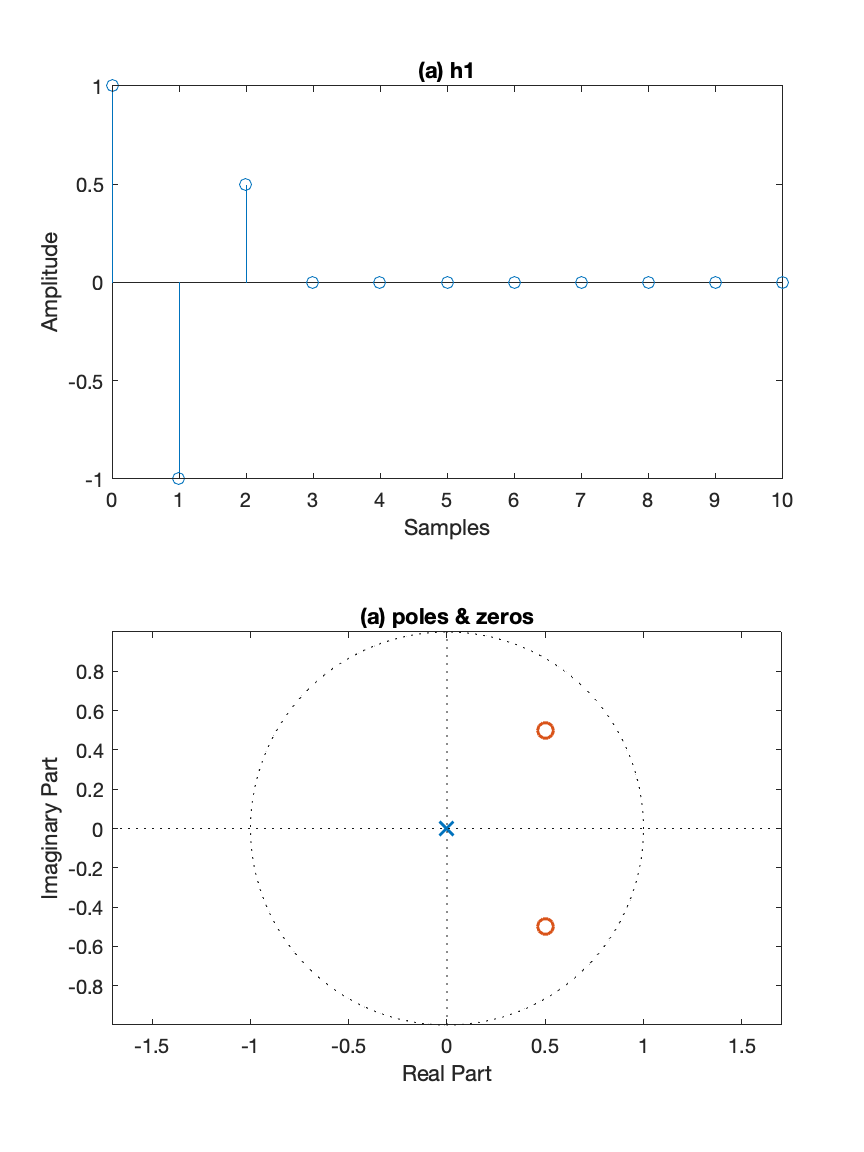

figure; 
set(gcf,'Units','Inches', 'Position', [0 0 6 8])
subplot(2,1,1); stem(n, h1); title('(a) h1');
xlabel('Samples'); ylabel('Amplitude');
subplot(2,1,2); pzplot(H1_B, H1_A); title('(a) poles & zeros');

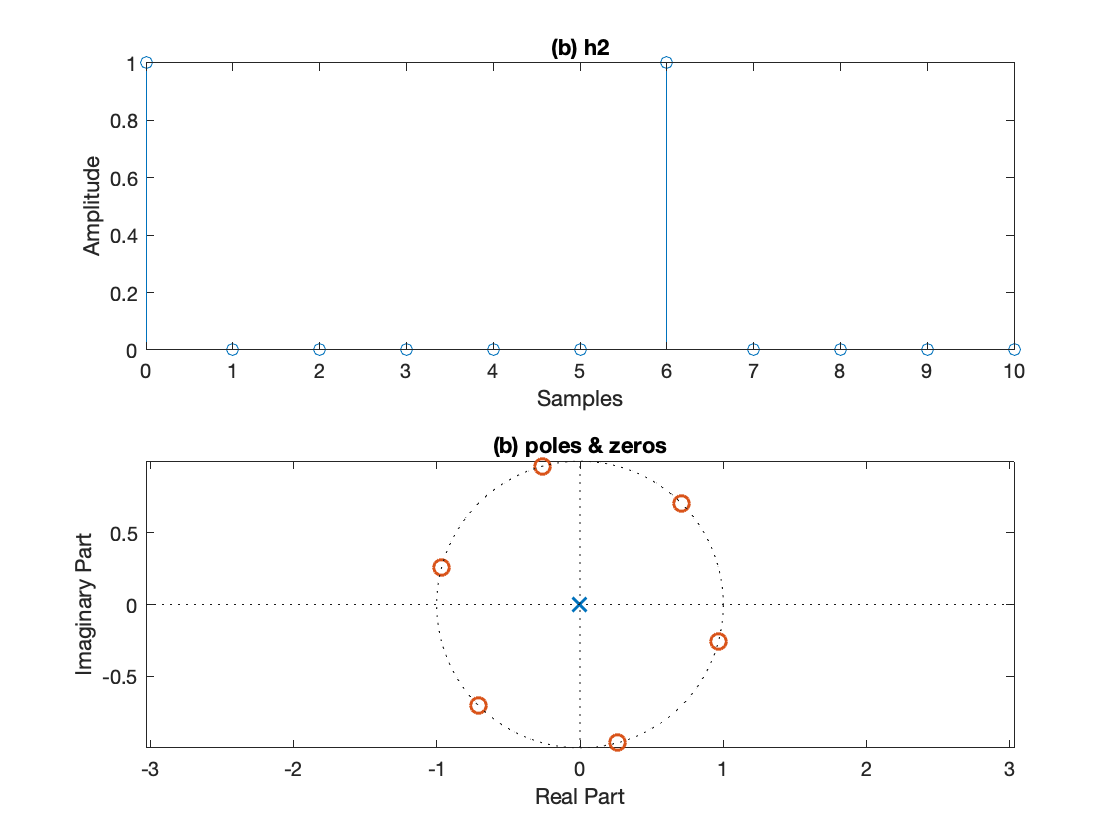

figure;
subplot(2,1,1); stem(n, abs(h2)); title('(b) h2'); %note that we plot absolute value for complex h
xlabel('Samples'); ylabel('Amplitude');
subplot(2,1,2); pzplot(H2_B, H2_A); title('(b) poles & zeros');

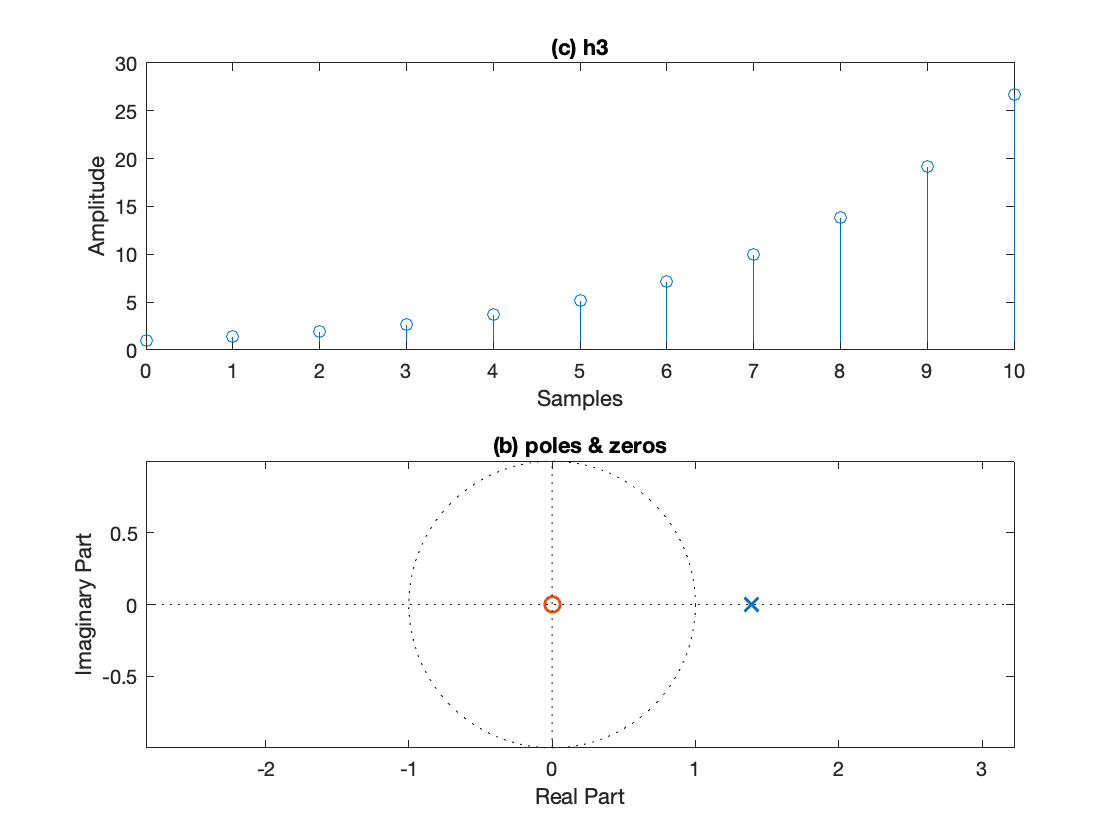

figure;
subplot(2,1,1); stem(n, h3); title('(c) h3');
xlabel('Samples'); ylabel('Amplitude');
subplot(2,1,2); pzplot(H3_B, H3_A); title('(b) poles & zeros');

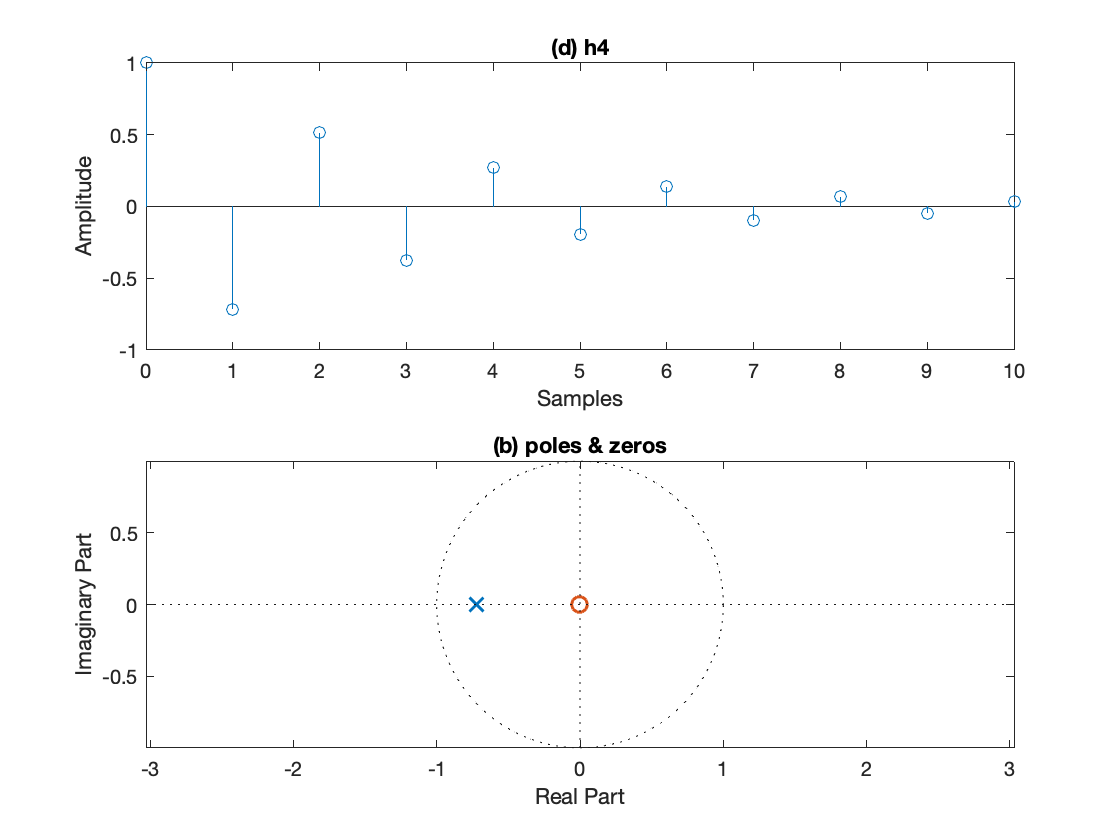

figure;
subplot(2,1,1); stem(n, h4); title('(d) h4');
xlabel('Samples'); ylabel('Amplitude');
subplot(2,1,2); pzplot(H4_B, H4_A); title('(b) poles & zeros');

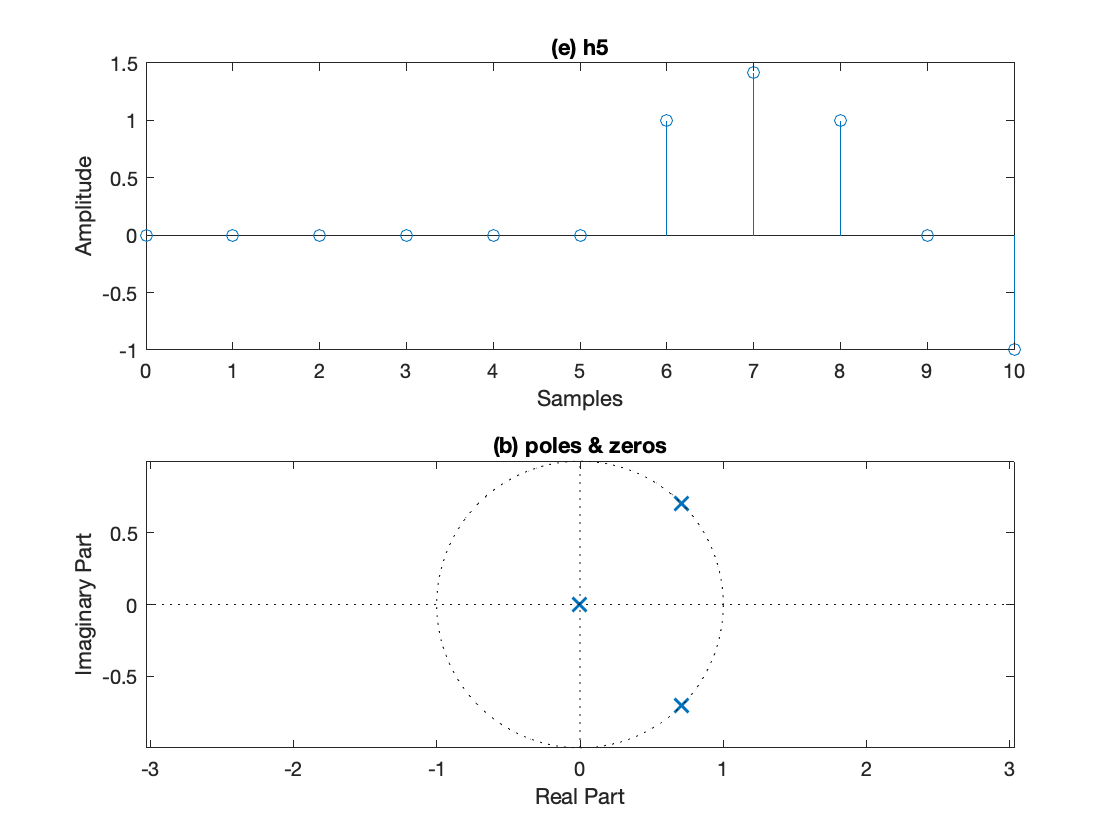

figure;
subplot(2,1,1); stem(n, h5); title('(e) h5');
xlabel('Samples'); ylabel('Amplitude');
subplot(2,1,2); pzplot(H5_B, H5_A); title('(b) poles & zeros');

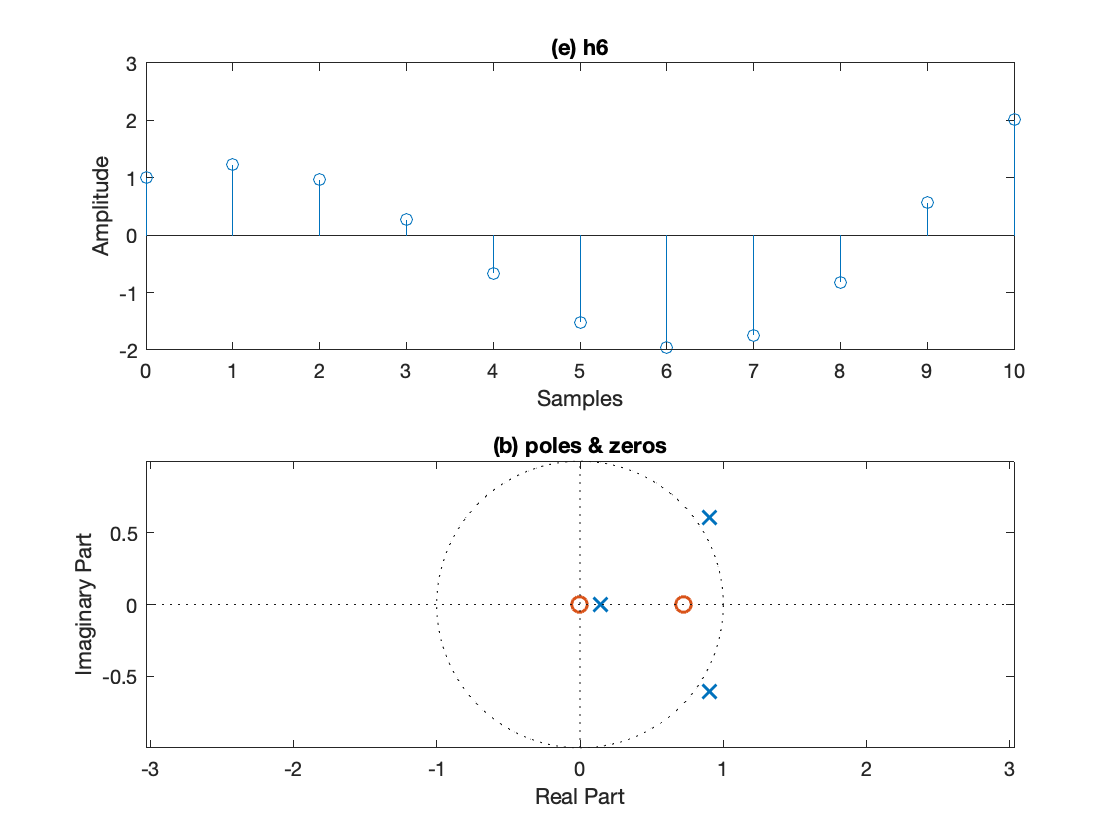

figure;
subplot(2,1,1); stem(n, h6); title('(e) h6');
xlabel('Samples'); ylabel('Amplitude');
subplot(2,1,2); pzplot(H6_B, H6_A); title('(b) poles & zeros');

**Supplementary Functions:**

function pzplot(b,a)
% PZPLOT(B,A)  plots the pole-zero plot for the filter described by
% vectors A and B.  The filter is a "Direct Form II Transposed"
% implementation of the standard difference equation:
% 
%    a(1)*y(n) = b(1)*x(n) + b(2)*x(n-1) + ... + b(nb+1)*x(n-nb)
%                          - a(2)*y(n-1) - ... - a(na+1)*y(n-na)
% 

    % MODIFY THE POLYNOMIALS TO FIND THE ROOTS 
    b  = b(1:find(b,1,'last'));
    a  = a(1:find(a,1,'last'));
    b1 = zeros(max(length(a),length(b)),1); % Need to add zeros to get the right roots
    a1 = zeros(max(length(a),length(b)),1); % Need to add zeros to get the right roots
    b1(1:length(b)) = b;    % New a with all values
    a1(1:length(a)) = a;    % New a with all values

    % FIND THE ROOTS OF EACH POLYNOMIAL AND PLOT THE LOCATIONS OF THE ROOTS
    h1 = plot(real(roots(a1)), imag(roots(a1)));
    hold on;
    h2 = plot(real(roots(b1)), imag(roots(b1)));
    hold off;

    % DRAW THE UNIT CIRCLE
    circle(0,0,1)
    
    % MAKE THE POLES AND ZEROS X's AND O's
    set(h1, 'LineStyle', 'none', 'Marker', 'x', 'MarkerFaceColor','none', 'linewidth', 1.5, 'markersize', 8); 
    set(h2, 'LineStyle', 'none', 'Marker', 'o', 'MarkerFaceColor','none', 'linewidth', 1.5, 'markersize', 8); 
    axis equal;
    
    % DRAW VERTICAL AND HORIZONTAL LINES
    xminmax = xlim();
    yminmax = ylim();
    line([xminmax(1) xminmax(2)],[0 0], 'linestyle', ':', 'linewidth', 0.5, 'color', [1 1 1]*.1)
    line([0 0],[yminmax(1) yminmax(2)], 'linestyle', ':', 'linewidth', 0.5, 'color', [1 1 1]*.1)
    
    % ADD LABELS AND TITLE
    xlabel('Real Part')
    ylabel('Imaginary Part')
    title('Pole-Zero Plot')
    
end


function circle(x,y,r)
% CIRCLE(X,Y,R)  draws a circle with horizontal center X, vertical center
% Y, and radius R. 
%
    
    % ANGLES TO DRAW
    ang=0:0.01:2*pi; 
    
    % DEFINE LOCATIONS OF CIRCLE
    xp=r*cos(ang);
    yp=r*sin(ang);
    
    % PLOT CIRCLE
    hold on;
    plot(x+xp,y+yp, ':', 'linewidth', 0.5, 'color', [1 1 1]*.1);
    hold off;
    
end